clear all; clc;
% cd(fileparts(which(mfilename)));  % In a .m file uncomment this
cd(fileparts(matlab.desktop.editor.getActiveFilename)); % In a .mlx file uncomment this

# Example: Double Pendulum

Develop a Kalman filter to track the state of the typical particle Double Pendulum. There is no friction. Sensor is a gyro in y ($\omega_y$) and 2 axis accelerometers ($a_x$, $a_z$) on the second pendulum tip with axes along directions $1'$ and $3'$:


$$\mathbf{z}=\left[\begin{array}{c}\omega_y(\mathbf{x},\mathbf{\dot{\mathbf{x}}}) \\ a_x(\mathbf{x},\mathbf{\dot{\mathbf{x}}})\\ a_z(\mathbf{x},\mathbf{\dot{\mathbf{x}}})\end{array}\right]$$


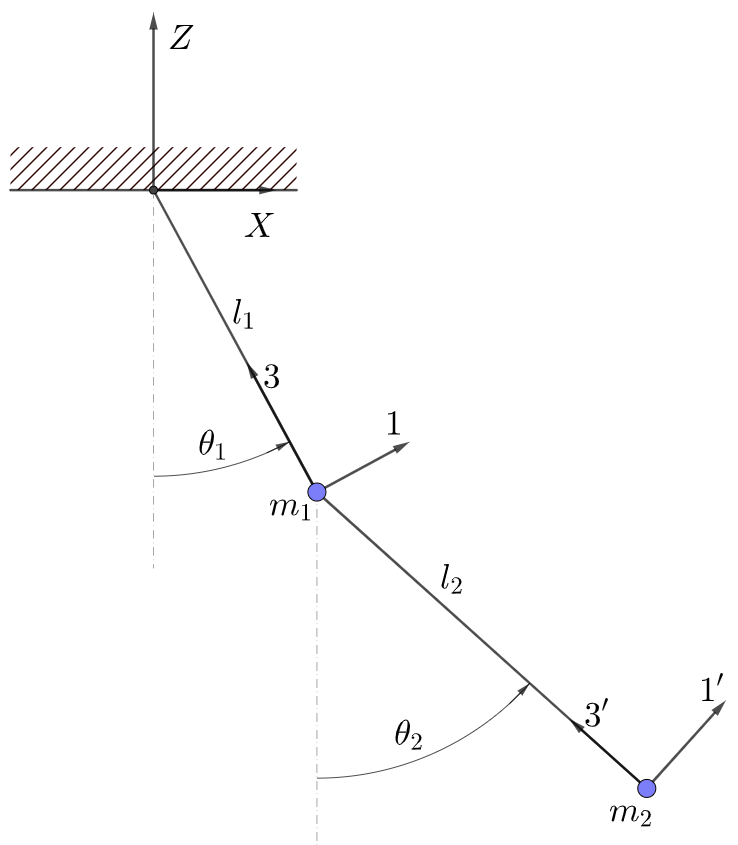

Determine transition process equations & sensor equations, and the required Jacobians.

# Solution:

## This is the first part of the solution: Determine model and sensor equations, and export the required functions for simulation and Kalman filtering.

The derivative w.r.t. time of the state, $\dot{\mathbf{x}}(\mathbf{x},\mathbf{u},t)$ It is used to simulate the "true state" $\mathbf{x}^{tr}$.

$\dot{\mathbf{x}}(\mathbf{x},\mathbf{u},t)$ is used to define the discretized model, $\mathbf{x}_{k+1}=\mathbf{f}(\mathbf{x}_{k},\mathbf{u}_k,t_0+k~\Delta t)$ used in the Kalman filter.

$\mathbf{h}$, $\mathbf{z}_{k+1}=\mathbf{h}(\mathbf{x}_{k+1},\mathbf{u}_{k+1},t_0+(k+1)~\Delta t)$, is used to define the "true mesurements" in terms of the "true state" that is contamined with noise to generate noisy measurements.

$\mathbf{f}$ and $\mathbf{h}$ and their Jacobians w.r.t. state, $\mathbf{x}$, and input, $\mathbf{u}$, $\mathbf{f}_\mathbf{x}$, $\mathbf{f}_\mathbf{{u}$, $\mathbf{h}_\mathbf{x}$, $\mathbf{h}_\mathbf{{u}$, must be exported.

syms t...
     theta1 dtheta1 ddtheta1...
     theta2 dtheta2 ddtheta2...
     m1 m2 l1 l2 g Delta_t     real
param=[m1 m2 l1 l2 g Delta_t]';

Generalized coordinate, velocity and acceleration vectors:

$\mathbf{q}=\left[\begin{array}{c}
\theta_1\\
\theta_2
\end{array}\right]$,$\dot{\mathbf{q}}=\left[\begin{array}{c}
\dot{\theta}_1\\
\dot{\theta}_1
\end{array}\right]$and $\ddot{\mathbf{q}}=\left[\begin{array}{c}
\ddot{\theta}_1\\
\ddot{\theta}_1
\end{array}\right]$

q=[theta1, theta2]';
dq=[dtheta1, dtheta2]';
ddq=[ddtheta1, ddtheta2]';

Forces acting on the particle. Inertia & gravity (gravity not defined not required):

$^{I}\mathbf{f}^{P_1}=-m_1 ~\mathbf{a}^{P_1}=-m_1...$, $^{g}\mathbf{f}^{P_1}=-m_1~g~\mathbf{e}_y$

$^{I}\mathbf{f}^{P_2}=-m_2 ~\mathbf{a}^{P_2}=-m_2...$, $^{g}\mathbf{f}^{P_2}=-m_2~g~\mathbf{e}_y$

Particle velocity:


$$\mathbf{v}^{P1}=l_1~\dot{\theta}_1 ~\mathbf{e}_1$$



$$\mathbf{v}^{P2}=\mathbf{v}^{P1}+l_2~\dot{\theta}_2 ~\mathbf{e}_{1'}$$


Virtual power equations:


$$^{I}\mathbf{f}^{P_1}\cdot\frac{\partial~\mathbf{v}^{P_1} }{\partial~ \dot{\mathbf{q}}}+^{I}\mathbf{f}^{P_2}\cdot\frac{\partial~\mathbf{v}^{P_2} }{\partial~ \dot{\mathbf{q}}}+^{g}\mathbf{f}^{P_1}\cdot\frac{\partial~\mathbf{v}^{P_1} }{\partial~ \dot{\mathbf{q}}}+^{g}\mathbf{f}^{P_2}\cdot\frac{\partial~\mathbf{v}^{P_2} }{\partial~ \dot{\mathbf{q}}}=\mathbf{0}$$


acc_P1=[cos(theta1), 0,-sin(theta1);
        0,           1, 0;
        sin(theta1), 0, cos(theta1)]*[ddtheta1*l1;
                                      0
                                      dtheta1^2*l1];%xyz
    
acc_P2=acc_P1+[cos(theta2), 0,-sin(theta2);
           0,           1, 0;
           sin(theta2), 0, cos(theta2)]*[ddtheta2*l2;
                                         0
                                         dtheta2^2*l2];%xyz
                               
iF_P1=-m1*acc_P1; %xyz
iF_P2=-m2*acc_P2; %xyz
gF_P1=[0,0,-m1*g]'; %xyz
gF_P2=[0,0,-m2*g]'; %xyz

v_P1=[cos(theta1), 0,-sin(theta1);
      0,           1, 0;
      sin(theta1), 0, cos(theta1)]*[dtheta1*l1;
                                    0
                                    0]; %xyz
v_P2=v_P1+[cos(theta2), 0,-sin(theta2);
           0,           1, 0;
           sin(theta2), 0, cos(theta2)]*[dtheta2*l2;
                                         0
                                         0]; %xyz
                               
Dyn_eq=-((iF_P1'*jacobian(v_P1,dq))'+...
     (iF_P2'*jacobian(v_P2,dq))'+...
     (gF_P1'*jacobian(v_P1,dq))'+...
     (gF_P2'*jacobian(v_P2,dq))'); Dyn_eq=simplify(Dyn_eq)

 
Dyn_eq =
 
l1*(l2*m2*sin(theta1 - theta2)*dtheta2^2 + g*m1*sin(theta1) + g*m2*sin(theta1) + ddtheta1*l1*m1 + ddtheta1*l1*m2 + ddtheta2*l2*m2*cos(theta1 - theta2))
                                           l2*m2*(- l1*sin(theta1 - theta2)*dtheta1^2 + ddtheta2*l2 + g*sin(theta2) + ddtheta1*l1*cos(theta1 - theta2))
 


Virtual power dynamic equations structure


$$\mathbf{M}_{\dot{\mathbf{q}}\dot{\mathbf{q}}}~\ddot{\mathbf{q}}-{\mathbf{\delta}}_{\dot{\mathbf{q}}}=\mathbf{0}$$


M_qq=jacobian(Dyn_eq,ddq); M_qq=simplify(M_qq)

 
M_qq =
 
[               l1^2*(m1 + m2), l1*l2*m2*cos(theta1 - theta2)]
[l1*l2*m2*cos(theta1 - theta2),                       l2^2*m2]
 


delta_q=-subs(Dyn_eq,ddq,zeros(size(ddq))); delta_q=simplify(delta_q)

 
delta_q =
 
-l1*(l2*m2*sin(theta1 - theta2)*dtheta2^2 + g*m1*sin(theta1) + g*m2*sin(theta1))
                    -l2*m2*(- l1*sin(theta1 - theta2)*dtheta1^2 + g*sin(theta2))
 


Therefore $\ddot{\mathbf{q}}(\mathbf{x},\mathbf{u},t)=\mathbf{M}_{\dot{\mathbf{q}}\dot{\mathbf{q}}} ^{-1}~\mathbf{\delta}_{\dot{\mathbf{q}}}$

ddq_func=inv(M_qq)*delta_q; ddq_func=simplify(ddq_func)

 
ddq_func =
 
                                                                                               -(l1*m2*sin(2*theta1 - 2*theta2)*dtheta1^2 + 2*l2*m2*sin(theta1 - theta2)*dtheta2^2 + 2*g*m1*sin(theta1) + g*m2*sin(theta1) + g*m2*sin(theta1 - 2*theta2))/(l1*(2*m1 + m2 - m2*cos(2*theta1 - 2*theta2)))
(l1*cos(theta1 - theta2)*(l2*m2*sin(theta1 - theta2)*dtheta2^2 + g*m1*sin(theta1) + g*m2*sin(theta1)))/(- l1*l2*m2*cos(theta1 - theta2)^2 + l1*l2*m1 + l1*l2*m2) - (l2*m2*(m1 + m2)*(- l1*sin(theta1 - theta2)*dtheta1^2 + g*sin(theta2)))/(- l2^2*m2^2*cos(theta1 - theta2)^2 + l2^2*m2^2 + m1*l2^2*m2)
 


x_=[q;dq]

 
x_ =
 
 theta1
 theta2
dtheta1
dtheta2
 


$\mathbf{u}$ is  empty (not defined in this problem).

u=sym([])

 
u =
 
[ empty sym ]
 



$$\dot{\mathbf{x}}(\mathbf{x},t)=\left[\begin{array}{c} \dot{\mathbf{q}} \\ \ddot{\mathbf{q}}(\mathbf{q},\dot{\mathbf{q}},t)\end{array}\right]$$


dstate=[dq;ddq_func]; dstate=simplify(dstate)

 
dstate =
 
                                                                                                                                                                                                                                                                                                 dtheta1
                                                                                                                                                                                                                                                                                                 dtheta2
                                                                                               -(l1*m2*sin(2*theta1 - 2*theta2)*dtheta1^2 + 2*l2*m2*sin(theta1 - theta2)*dtheta2^2 + 2*g*m1*sin(theta1) + g*m2*sin(theta1) + g*m2*sin(theta1 - 2*theta2))/(l1*(2*m1 + m2 - m2*cos(2*theta1 - 2*theta2)))
(l1*cos(theta1 - theta2)*(l2*m2*sin(theta1 - theta2)*dtheta2^2 + g*m1*sin(theta1) + g*m2*sin(the

$\dot{\mathbf{x}}_{\mathbf{x}}(\mathbf{x},t)=\frac{\partial~\dot{\mathbf{x}}(\mathbf{x},t)}{\partial ~\mathbf{x}}$, can be usefull if using exponential integration discretization.

dstate_x=jacobian(dstate,x_)

 
dstate_x =
 
[                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                      0,                                                                                                                                                                

f=x_+dstate*Delta_t; f=simplify(f) %x_k+1=f(x_k)

 
f =
 
                                                                                                                                                                                                                                                                         theta1 + Delta_t*dtheta1
                                                                                                                                                                                                                                                                         theta2 + Delta_t*dtheta2
                                                                     dtheta1 - (Delta_t*(l1*m2*sin(2*theta1 - 2*theta2)*dtheta1^2 + 2*l2*m2*sin(theta1 - theta2)*dtheta2^2 + 2*g*m1*sin(theta1) + g*m2*sin(theta1) + g*m2*sin(theta1 - 2*theta2)))/(l1*(2*m1 + m2 - m2*cos(2*theta1 - 2*theta2)))
dtheta2 + (Delta_t*(g*m1*sin(2*theta1 - theta2) - g*m2*sin(theta2) - g*m1*sin(theta2) + g*m2*sin(2*theta1 - theta2) + 2*dt

f_x=jacobian(f,x_); f_x=simplify(f_x)

 
f_x =
 
[                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                1,                                                                                                                                                                                                                                                                                                                                                                                                                                           

f_u=jacobian(f,u); f_u=simplify(f_u)

 
f_u =
 
Empty sym: 4-by-0
 


Acceleration sensors require defining acceleration in sensors base $B\theta_2\equiv1'2'3'$ in terms of the state $\mathbf{x}$.

acc_P2_Btheta2=simplify(subs([cos(theta2), 0,-sin(theta2);
                              0,           1, 0;
                              sin(theta2), 0, cos(theta2)]'*(acc_P2-[0,0,-g]'),...
                             ddq,ddq_func));
h=[dtheta2;
   acc_P2_Btheta2'*[1,0,0]'
   acc_P2_Btheta2'*[0,0,1]']; h=simplify(h)

 
h =
 
                                                                                                                                         dtheta2
                                                                                                                                               0
(m1*(2*l1*cos(theta1 - theta2)*dtheta1^2 + 2*l2*dtheta2^2 + g*cos(2*theta1 - theta2) + g*cos(theta2)))/(2*m1 + m2 - m2*cos(2*theta1 - 2*theta2))
 


h_x=jacobian(h,x_); h_x=simplify(h_x)

 
h_x =
 
[                                                                                                                                                                                                                                                                                                     0,                                                                                                                                                                                                                                                                                                                  0,                                                                                0,                                                           1]
[                                                                                                                                                                                                                                                 

h_u=jacobian(h,u); h_u=simplify(h_u)

 
h_u =
 
Empty sym: 3-by-0
 


matlabFunction(f,'file','f','vars',{x_ u t param});
matlabFunction(f_x,'file','f_x','vars',{x_ u t param});
matlabFunction(f_u,'file','f_u','vars',{x_ u t param});
matlabFunction(h,'file','h','vars',{x_ u t param});
matlabFunction(h_x,'file','h_x','vars',{x_ u t param});
matlabFunction(h_u,'file','h_u','vars',{x_ u t param});
matlabFunction(dstate,'file','dstate','vars',{x_ u t param});
matlabFunction(dstate_x,'file','dstate_x','vars',{x_ u t param});